% syms s t;
s = tf('s');

student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

G1 = 1/(s+sn_A);
G2 = 1/(s+sn_B);
G3 = 1/(s+sn_C);
G4 = 1/(s+sn_D);
G5 = 1/(s+sn_E);

H1 = 1/(s+sn_F);
H2 = 1/(s+sn_G);

A = G1*G5*H2;
C = G2*G4*H1+G3;

C1_G11 = G1/(1/G2-A*C/G2);

[z, p , k] = zpkdata(C1_G11);
[num_c1, den_c1] = tfdata(C1_G11, 'v');
zeros = cell2mat(z)

zeros =  -18.0000 + 0.0000i
 -15.0000 + 0.0000i
 -14.0000 + 0.0000i
 -13.0000 + 0.0001i
 -13.0000 - 0.0001i
 -11.0000 + 0.0000i
 -11.0000 - 0.0000i


poles = cell2mat(p)

poles =  -18.0004 + 0.0000i
 -18.0001 + 0.0000i
 -14.9767 + 0.0000i
 -14.2622 + 0.0000i
 -12.9193 + 0.6464i
 -12.9193 - 0.6464i
 -13.0000 + 0.0000i
 -11.0000 + 0.0000i
 -10.9221 + 0.0000i


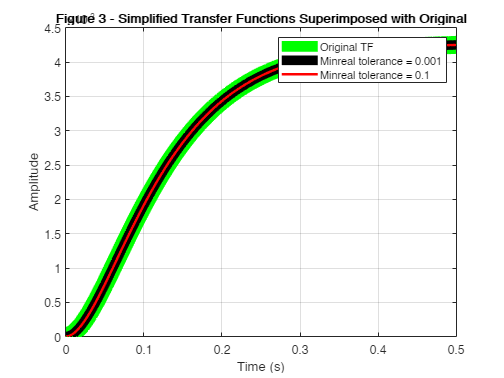


hold off

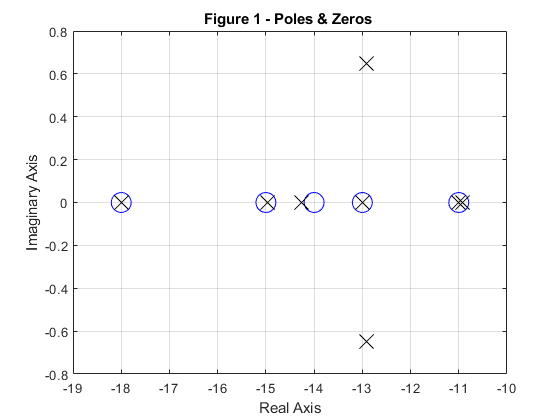

figure(1);
plot(zeros, 'o', 'MarkerSize', 15, 'Color','Blue')
grid on
hold on
plot(poles, 'x', 'MarkerSize', 15, 'Color','Black')
title('Figure 1 - Poles & Zeros ')
xlabel('Real Axis')
ylabel('Imaginary Axis')

hold off

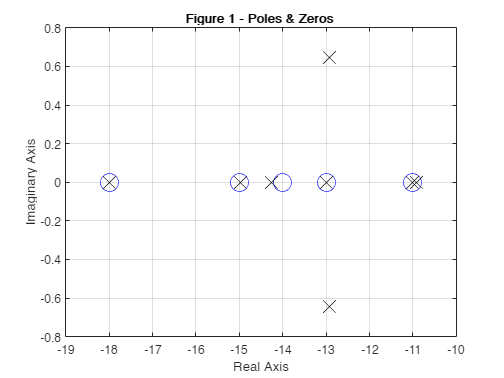

% poles

tol0 = 0;
tol3 = 1e-3;
tol1 = 1e-1;

% tol0
[z0, p0 , k0] = zpkdata(minreal(C1_G11));
zeros0 = cell2mat(z0);
poles0 = cell2mat(p0);

%tol1
[z1, p1, k1] = zpkdata(minreal(C1_G11, tol1));
zeros1 = cell2mat(z1);
poles1 = cell2mat(p1);

%tol3
[z3, p3 , k3] = zpkdata(minreal(C1_G11, tol3));
zeros3 = cell2mat(z3);
poles3 = cell2mat(p3);

hold off

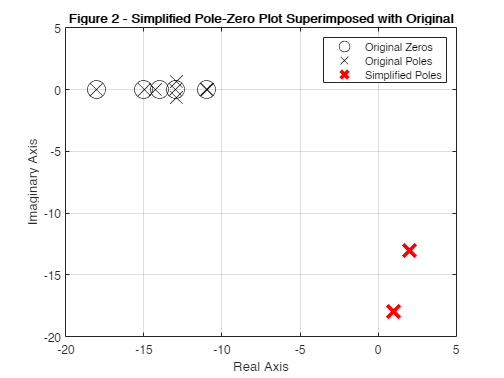

figure(2);
% plot original
plot(zeros0, 'o', 'MarkerSize', 15, 'Color','Black');
grid on
hold on
plot(poles0, 'x', 'MarkerSize', 15, 'Color','Black');

% plot(zeros, 'o', 'MarkerSize', 15, 'Color','Blue');
% plot(poles, 'x', 'MarkerSize', 15, 'Color','Blue');


% plot tol1
plot(zeros1, 'o', 'MarkerSize', 15, 'Color','Red', 'LineWidth', 3);
plot(poles1, 'x', 'MarkerSize', 15, 'Color','Red', 'LineWidth', 3);

title('Figure 2 - Simplified Pole-Zero Plot Superimposed with Original');
xlabel('Real Axis');
ylabel('Imaginary Axis');
legend('Original Zeros', 'Original Poles', 'Simplified Poles')

hold off

% step responess

[y0, t0] = step(minreal(C1_G11));
[y1, t1] = step(minreal(C1_G11, tol1));
[y3, t3] = step(minreal(C1_G11, tol3));

hold off

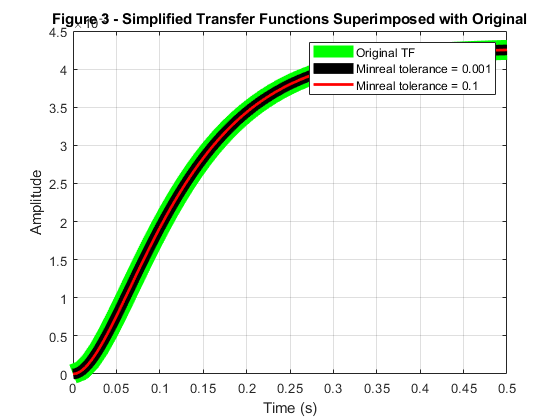

figure(3);
plot(t0, y0, 'Color', 'Green', 'LineWidth', 15);
hold on
plot(t3, y3, 'Color', 'Black', 'LineWidth', 8);
plot(t1, y1, 'Color', 'Red', 'LineWidth', 2);

axis([0, 0.5, 0, 4.5e-3])
title('Figure 3 - Simplified Transfer Functions Superimposed with Original');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original TF', 'Minreal tolerance = 0.001', 'Minreal tolerance = 0.1')
grid on
hold off

% turning the blocks into num and den
% 
% G1 = 1/(s+sn_A);
% G2 = 1/(s+sn_B);
% G3 = 1/(s+sn_C);
% G4 = 1/(s+sn_D);
% G5 = 1/(s+sn_E);
% 
% H1 = 1/(s+sn_F);
% H2 = 1/(s+sn_G);

[numG1, denG1] = tfdata(G1, 'v');
[numG2, denG2] = tfdata(G2, 'v');
[numG3, denG3] = tfdata(G3, 'v');
[numG4, denG4] = tfdata(G4, 'v');
[numG5, denG5] = tfdata(G5, 'v');

[numH1, denH1] = tfdata(H1, 'v');
[numH2, denH2] = tfdata(H2, 'v');

[numtol0, dentol0] = tfdata(minreal(C1_G11), 'v');